load("Internet.mat")

MB = internet(:,1)

MB =    163
   170
   169
   173
   160
   168
   163
   173
   168
   165


connection = internet(:,2)

connection =     1.1000
    3.5000
    3.0000
    2.0000
    1.1000
    5.2000
    2.2000
    1.7000
    1.9000
    2.0000


x = MB;
v = connection;
b = 1024; % MB -> KB conversion factor
d = 3600; % h -> s conversion factor
y = 0 + b*x;
u = 0 + d*v;

R_x_v = corrcoef(x,v)

R_x_v =     1.0000    0.7686
    0.7686    1.0000


R_y_u = corrcoef(y,u)

R_y_u =     1.0000    0.7686
    0.7686    1.0000


check = all([R_y_u == (b*d)/abs(b*d)*R_x_v, ...
    R_y_u == (b*d)/(b*d) * R_x_v, ...
    R_y_u == R_x_v], "all")

check = logical
   1


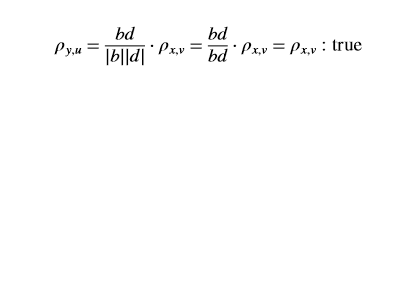

expression = "\rho_{y,u} = \frac{b d}{\left| b \right| \left| d \right|} " + ...
    "\cdot \rho_{x,v} = \frac{b d}{b d} \cdot \rho_{x,v} = \rho_{x,v}";
expression = sprintf("$%s : \\mathrm{%s}$", expression, string(expr_check));

clf;
axis off;
text(0, 1, expression, Interpreter="latex", FontSize=14, Units="normalized", ...
    HorizontalAlignment="left", VerticalAlignment="top")